# Válogatott modellek a matematikai biológiában

# 1. gyakorlat

## Markov egere

A teret $n = 3$ helyiségre bontjuk:

n = 3;

Szomszédsági mátrix

A = [
    0   1/3 1/3
    1/2 0   2/3
    1/2 2/3 0  ];

#### Egér mozgásának szimulációja

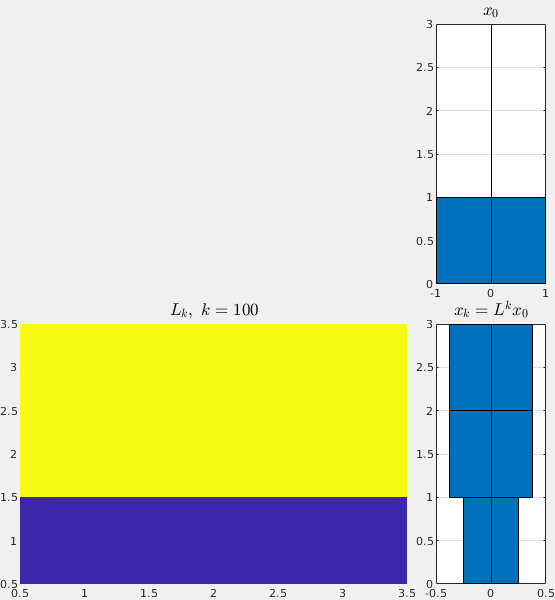

% Gr = digraph(L');
% Pl_Gr = plot(Gr);
x0 = [1;0;0];
T = 100;

fig = figure(123);
fig.Position(3:4) = [555,600];
fig.Visible = 'on';

Tl = tiledlayout(2,4,"TileSpacing","tight","Padding","tight","TileIndexing","rowmajor");

ax1 = nexttile(4); hold on, grid on, box on
Br0 = barh(0.5:n,[x0 -x0],1,'stacked');
Br0(2).FaceColor = Br0(1).FaceColor;
ylim([0,n])
title('$x_0$','Interpreter','latex','FontSize',12)

ax2 = nexttile(5,[1,3]); hold on, grid on, box on;
Img = imagesc(A);
Tl = title("$L_k,~ \makebox[2cm]{$k = 1\hfill$}$",'Interpreter','latex','FontSize',12);

ax3 = nexttile(8); hold on, grid on, box on;
Brn = barh(0.5:n,A*[x0 -x0],1,'stacked');
Brn(2).FaceColor = Brn(1).FaceColor;
ylim([0,n])
title('$x_k = L^k x_0$','Interpreter','latex','FontSize',12)

Ak = eye(n);
for k = 1:T
    Ak = Ak*A;
    xk = Ak*x0;
    se_hatv = eig(Ak);

    Brn(1).YData = xk;
    Brn(2).YData = -xk;
    
    Img.CData = Ak;

    Tl.String = "$L_k,~ k = " + num2str(k) + "$";
    drawnow
end